## Plot voltages

SCR_grid_vec = [1.5 2 3 3 5];
X_R_ratio_grid_vec = [5 5 5 10 15];

n_cases = length(X_R_ratio_grid_vec);
for i = 1:n_cases
    SCR_grid = SCR_grid_vec(i)
    X_R_ratio_grid = X_R_ratio_grid_vec(i) %3;

    strucFileName = "SCR"+num2str(floor(SCR_grid))+"_" +num2str(mod(SCR_grid,1)*10)+"_" +"XR"+X_R_ratio_grid
    load("sim_data_" + strucFileName + ".mat","struc_RMSvoltcurr",'-mat')

    t = struc_RMSvoltcurr.time;

    v_LOAD = struc_RMSvoltcurr.signals(1).values(:,1);
    v_GRID = struc_RMSvoltcurr.signals(1).values(:,4);
    v_GFM = struc_RMSvoltcurr.signals(1).values(:,7);
    



## Visualize

SCR_grid = 1.5000

X_R_ratio_grid = 5

strucFileName = "SCR1_5_XR5"

plotTitle = "SCR: 1.5 X/R: 5"

figName = "SCR1_5_XR5"

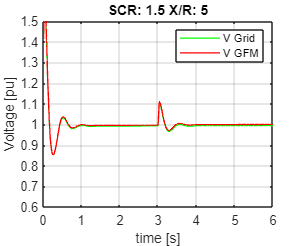

SCR_grid = 2

X_R_ratio_grid = 5

strucFileName = "SCR2_0_XR5"

plotTitle = "SCR: 2 X/R: 5"

figName = "SCR2_0_XR5"

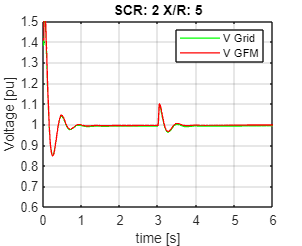

SCR_grid = 3

X_R_ratio_grid = 5

strucFileName = "SCR3_0_XR5"

plotTitle = "SCR: 3 X/R: 5"

figName = "SCR3_0_XR5"

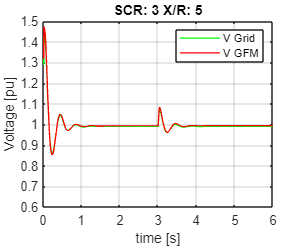

SCR_grid = 3

X_R_ratio_grid = 10

strucFileName = "SCR3_0_XR10"

plotTitle = "SCR: 3 X/R: 10"

figName = "SCR3_0_XR10"

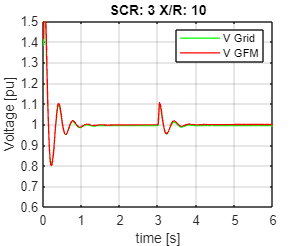

SCR_grid = 5

X_R_ratio_grid = 15

strucFileName = "SCR5_0_XR15"

plotTitle = "SCR: 5 X/R: 15"

figName = "SCR5_0_XR15"

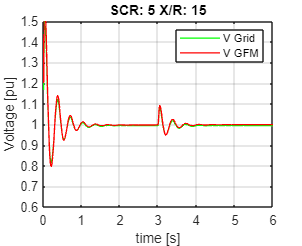



    plotTitle = "SCR: " + SCR_grid + " X/R: " + X_R_ratio_grid
    figName = "SCR"+num2str(floor(SCR_grid))+"_" +num2str(mod(SCR_grid,1)*10)+"_" +"XR"+X_R_ratio_grid
    figure('Name','RMS Voltage'+ figName,'units', 'centimeters','Position',[0.1 0.1 8 6.5])
    hold on
    grid on
    box on
    
    plot(t,v_GRID,'g-',LineWidth=1);
    plot(t,v_GFM,'r-',LineWidth=1);
    % plot(t,v_LOAD,'m-',LineWidth=1);
    title(plotTitle,Interpreter="tex")
    
    axis([0 6 0.6 1.5])
    legend('V Grid', 'V GFM') %'Detailed WPP model onshore PoC','Aggregated WPP model onshore PoC','Location','NorthOutside') ;
    xlabel('time [s]')
    ylabel('Voltage [pu]')
    ay = gca;
    ay.YTick = 0.6:0.1:1.5;
    ay.XTick =0:1:6;
    
    hold off
    
    set(gcf,'paperunits','centimeters','Paperposition',[0 0 6.5 6.5])
    plot_file_name = "RMS_voltage"+ figName +".png";
    exportgraphics(gcf,plot_file_name)
    plot_file_name = "RMS_voltage"+ figName +".pdf";
    
    exportgraphics(gcf,plot_file_name)

end    